# Two-Link Manipulator Control Study

## System matrices

A = [0 1 0 0;32.79 0 6.625 0;0 0 0 1;-67.38 0 -8.92 0];
B = [0 0; 4.65 -7.94;0 0;-7.94 27.27];
C = [1 0 0 0;0 0 1 0];
D = zeros(2,2);

Mr = ctrb(A,B);
sys = ss(A,B,eye(4),zeros(4,2));

RangoMr=rank(Mr)

RangoMr = 4

opt = RespConfig;
opt.Amplitude=0.26;
eig(sys)

ans =   -3.4886 + 0.4852i
  -3.4886 - 0.4852i
   3.4886 + 0.4852i
   3.4886 - 0.4852i


## Control specifications and feedback gain

PO = 5;
Ta = 15;

zita=abs(log(PO/100))/sqrt(pi^2+log(PO/100)^2);
omegan=4/(zita*Ta);

zita = 0.8;

p1 = -omegan*zita + omegan*sqrt(1-zita^2)*1i;
p2 = -omegan*zita - omegan*sqrt(1-zita^2)*1i;
p3 = -10*abs(p1); 
p4 = p3-1;
p5 = p4-1;
p6 = p5-1;


pcc = [p1 p2 p3 p4]; 
K = place(A,B,pcc);
eig(A-B*K)

ans =   -0.3091 + 0.2318i
  -0.3091 - 0.2318i
  -3.8641 + 0.0000i
  -4.8641 + 0.0000i



sys.InputName={'Torque1','Torque2'};
sys.OutputName={'P1','V1','P2','V2'};
stateFeedbackMatrix = ss([],[],[],K);
stateFeedbackMatrix.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrix.OutputName = {'sfaction1','sfaction2'};
SumT1 = sumblk('Torque1=reference1-sfaction1');
SumT2 = sumblk('Torque2=reference2-sfaction2');
SumT = append(SumT1,SumT2);
sysClk = connect(sys,stateFeedbackMatrix,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});


## Reference precompensation

tfMatrixPos = [sysClk(1,1) sysClk(1,2);sysClk(3,1) sysClk(3,2)];
gainMatrix = (dcgain(tfMatrixPos))^-1;
sysGM = ss([],[],[],gainMatrix);
sysGM.InputName = {'reference1','reference2'};
sysGM.OutputName = {'ref1_comp','ref2_comp'};
SumT1comp = sumblk('Torque1=ref1_comp-sfaction1');
SumT2comp = sumblk('Torque2=ref2_comp-sfaction2');
SumTcomp = append(SumT1comp,SumT2comp);
sysClkcomp = connect(sys,stateFeedbackMatrix,sysGM,SumTcomp,{'reference1','reference2'},{'P1','V1','P2','V2'});
tfP1comp = sysClkcomp(1,1)+sysClkcomp(1,2);

tfP2comp = sysClkcomp(3,1)+sysClkcomp(3,2);

## Integral action

Augmented system

Aaug = [A zeros(4,2);-C zeros(2,2)];
Baug = [B;zeros(2,2)];
Caug = [C zeros(2,2)];
Daug = D;

Mraug = ctrb(Aaug,Baug);
rangoMraug = rank(Aaug,Baug);
pccint = [p1 p2 p3 p4 p5 p6]; 
Kfinal = place(Aaug,Baug,pccint);
    

Closed-loop interconnection

sysItg = ss(zeros(2,2),eye(2),Kfinal(:,5:6),D);
sysItg.InputName={'errorP1','errorP2'};
sysItg.OutputName={'IntegralAction1','IntegralAction2'};
stateFeedbackMatrixfin = ss([],[],[],Kfinal(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1');
Sumint2 = sumblk('errorP2=reference2-P2');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysCli = connect(sys,stateFeedbackMatrixfin,sysItg,Sumi,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});

tfP1int = sysCli(1,1)+sysCli(1,2);

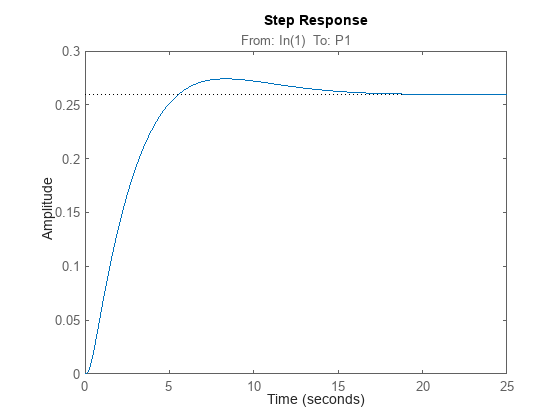

step(tfP1int,opt)

tfP2int = sysCli(3,1)+sysCli(3,2);



%% ITAE pole placement

%% Reference precompensation without integral action

wn = 1;

pITAE = roots([1 2.1*wn 3.4*wn^2 2.7*wn^3 wn^4]);
KITAE = place(A,B,pITAE);
sysClITAE = feedback(sys,KITAE);
stateFeedbackMatrixITAE = ss([],[],[],KITAE);
stateFeedbackMatrixITAE.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixITAE.OutputName = {'sfaction1','sfaction2'};
tfMatrixPosITAE = [sysClITAE(1,1) sysClITAE(1,2);sysClITAE(3,1) sysClITAE(3,2)];
gainMatrixITAE = (dcgain(tfMatrixPosITAE))^-1;
sysGMI = ss([],[],[],gainMatrixITAE);
sysGMI.InputName = {'reference1','reference2'};
sysGMI.OutputName = {'ref1_comp','ref2_comp'};
SumT1compI = sumblk('Torque1=ref1_comp-sfaction1');
SumT2compI = sumblk('Torque2=ref2_comp-sfaction2');
SumTcompI = append(SumT1compI,SumT2compI);
sysClITAE = connect(sys,stateFeedbackMatrixITAE,SumTcompI,sysGMI,{'reference1','reference2'},{'P1','V1','P2','V2'});
tfP1ITAE = sysClITAE(1,1)+sysClITAE(1,2);

tfP2ITAE = sysClITAE(3,1)+sysClITAE(3,2);

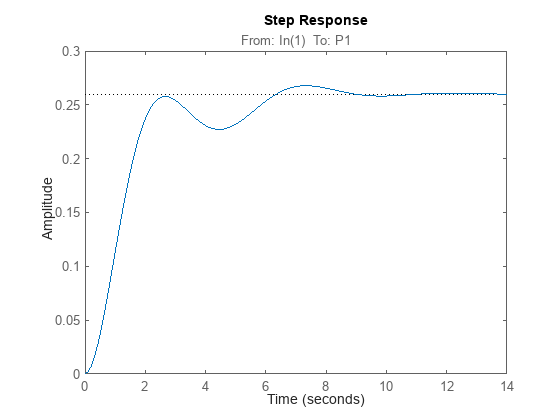

step(tfP1ITAE,opt);

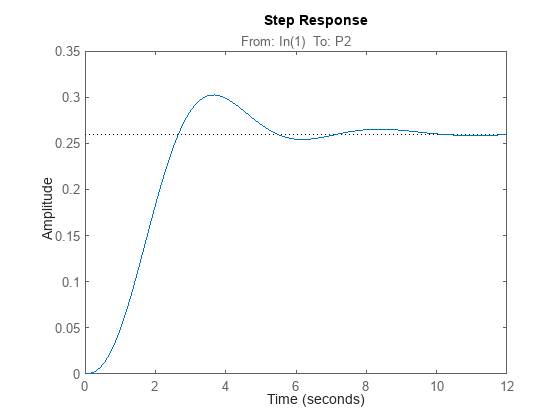

step(tfP2ITAE,opt);


%% Integral action

piITAE = roots([1 3.25*wn 6.6*wn^2 8.6*wn^3 7.45*wn^4 3.95*wn^5 wn^6]);
KiITAE = place(Aaug,Baug,piITAE);
sysItgI = ss(zeros(2,2),eye(2),KiITAE(:,5:6),D);
sysItgI.InputName={'errorP1','errorP2'};
sysItgI.OutputName={'IntegralAction1','IntegralAction2'};
stateFeedbackMatrixII = ss([],[],[],KiITAE(:,1:4));
stateFeedbackMatrixII.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixII.OutputName = {'sfaction1','sfaction2'};
Sumint1I = sumblk('errorP1=reference1-P1');
Sumint2I = sumblk('errorP2=reference2-P2');
SumiI = append(Sumint1I,Sumint2I);
SumT1I = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2I = sumblk('Torque2=-IntegralAction2-sfaction2');
SumTI = append(SumT1I,SumT2I);
sysCliI = connect(sys,stateFeedbackMatrixII,sysItgI,SumiI,SumTI,{'reference1','reference2'},{'P1','V1','P2','V2'});
tfP1ITAEI = sysCliI(1,1)+sysCliI(1,2);

tfP2ITAEI = sysCliI(3,1)+sysCliI(3,2);

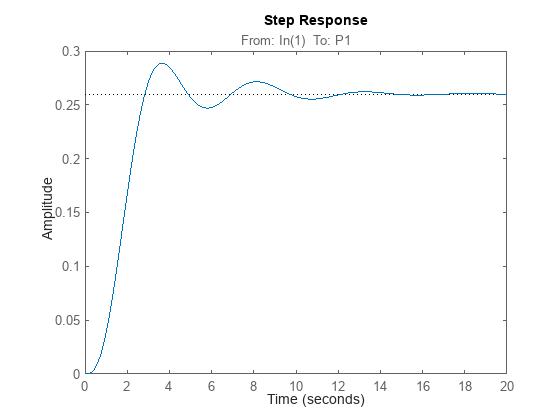

step(tfP1ITAEI,opt);

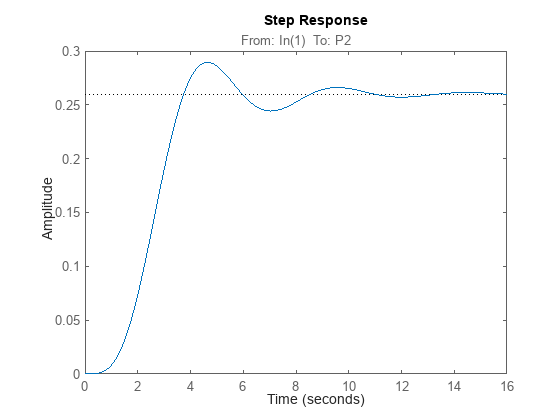

step(tfP2ITAEI,opt);

## Luenberger observer design


obspoles = [-20 -21 -22 -23];
L = place(A',C',obspoles);
Aobs = A-(L'*C);
Bobs = [B L'];
Cobs = eye(4);
Dobs = zeros(4);

stateFeedbackMatrixfin = ss([],[],[],Kfinal(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1H','V1H','P2H','V2H'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1H');
Sumint2 = sumblk('errorP2=reference2-P2H');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysobs = ss(Aobs,Bobs,Cobs,Dobs);
sysobs.InputName = {'Torque1','Torque2','P1','P2'};
sysobs.OutputName = {'P1H','V1H','P2H','V2H'};
sysCliO = connect(sys,stateFeedbackMatrixfin,sysItg,Sumi,SumT,sysobs,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysCliO(1,1)+sysCliO(1,2),opt)

# LQR with integral action

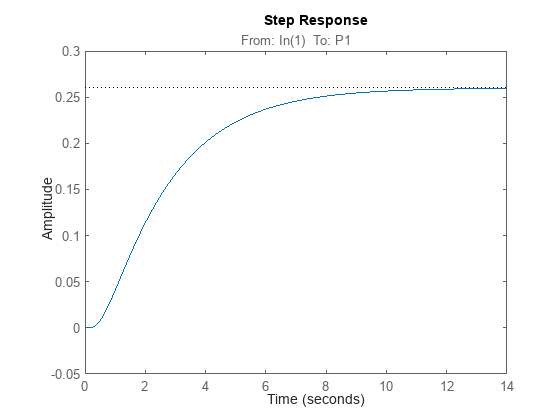

%% LQR with integral action

Qielements = [10 1 10 1 10 10];
Rielements = [1 1];
Qi = diag(Qielements);
Ri = diag(Rielements);
Aaug = [A zeros(4,2);-C zeros(2,2)];
Baug = [B;zeros(2,2)];
Caug = [C zeros(2,2)];
Daug = D;
QiO = Caug'*Caug;
QiO1 = 10*(Caug'*Caug)+blkdiag(zeros(4),1,1);

sysAug = ss(Aaug,Baug,Caug,Daug);
[Ki,~,~] = lqr(sysAug,Qi,Ri);

sysItg = ss(zeros(2,2),eye(2),Ki(:,5:6),D);
sysItg.InputName={'errorP1','errorP2'};
sysItg.OutputName={'IntegralAction1','IntegralAction2'};
stateFeedbackMatrixfin = ss([],[],[],Ki(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1');
Sumint2 = sumblk('errorP2=reference2-P2');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysCli = connect(sys,stateFeedbackMatrixfin,sysItg,Sumi,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysCli(1,1)+sysCli(1,2),opt)

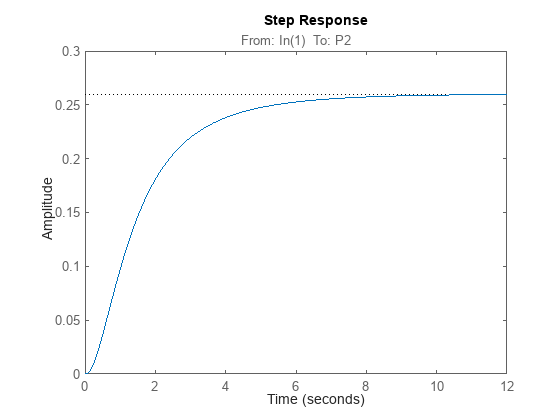

step(sysCli(3,1)+sysCli(3,2),opt)

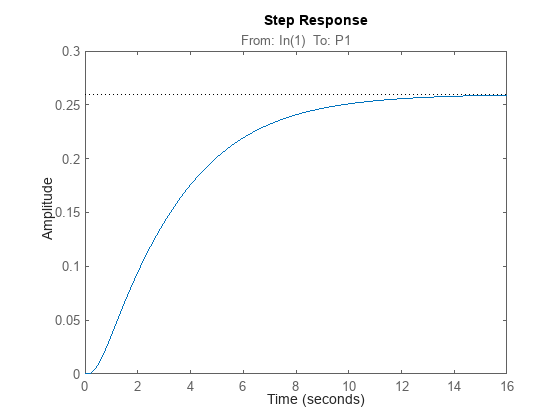

alfa =0.15;
Qielements = [1 1 1 1 1 1];
Rielements = [1 1];
Qi = diag(Qielements);
Ri = diag(Rielements);
[Ki,~,~] = lqr(Aaug+alfa*eye(6),Baug,Qi,Ri);
sysItg = ss(zeros(2,2),eye(2),Ki(:,5:6),D);
sysItg.InputName={'errorP1','errorP2'};
sysItg.OutputName={'IntegralAction1','IntegralAction2'};
stateFeedbackMatrixfin = ss([],[],[],Ki(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1');
Sumint2 = sumblk('errorP2=reference2-P2');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysCli = connect(sys,stateFeedbackMatrixfin,sysItg,Sumi,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysCli(1,1)+sysCli(1,2),opt)

step(sysCli(3,1)+sysCli(3,2),opt)


obspoles = [-20 -21 -22 -23]/3;
L = place(A',C',obspoles);
Aobs = A-(L'*C);
Bobs = [B L'];
Cobs = eye(4);
Dobs = zeros(4);


[KiO,~,~] = lqr(sysAug,QiO1,Ri);
[Ki,Si,Pi] = lqr(sysAug,Qi,Ri);



sysItg = ss(zeros(2,2),eye(2),KiO(:,5:6),D);
sysItg.InputName={'errorP1','errorP2'};
sysItg.OutputName={'IntegralAction1','IntegralAction2'};stateFeedbackMatrixfin = ss([],[],[],KiO(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1H','V1H','P2H','V2H'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1H');
Sumint2 = sumblk('errorP2=reference2-P2H');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysobs = ss(Aobs,Bobs,Cobs,Dobs);
sysobs.InputName = {'Torque1','Torque2','P1','P2'};
sysobs.OutputName = {'P1H','V1H','P2H','V2H'};
sysCliO = connect(sys,stateFeedbackMatrixfin,sysItg,Sumi,SumT,sysobs,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysCliO(1,1)+sysCliO(1,2),opt) 

## Kalman filter design

Qtildeelements = 1e-12*[1 1 1 1];
Rtildeelements = [0.0043/5 0.0043/5];
Qtilde=diag(Qtildeelements); 
Rtilde=diag(Rtildeelements);

sys4Kal = ss(A,[B eye(4)],C,[zeros(2,6)]);
[kalmf,L,P] = kalman(sys4Kal,Qtilde,Rtilde);
AobsK=kalmf.A;
BobsK=kalmf.B;
CobsK=eye(4);
DobsK=zeros(4,4);

## Mixed-sensitivity design


Ws=[zpk(makeweight(2000,[60,1],1/2000)) 0; 0 zpk(makeweight(2000,[30,1],1/2000))];
Wt=[zpk(makeweight(1/2000,[60,1],2000)) 0;0 zpk(makeweight(1/2000,[30,1],2000))]
Wk=diag([100,40])



[Kmix,CL,gamma]=mixsyn(sys,Ws,Wt,Wk);



## Plant discretization

A = [0 1 0 0;32.79 0 6.625 0;0 0 0 1;-67.38 0 -8.92 0];
B = [0 0; 4.65 -7.94;0 0;-7.94 27.27];
C = [1 0 0 0;0 0 1 0];
D = zeros(2,2);

Ts = 0.1;
sys = ss(A,B,eye(4),zeros(4,2));
sysdis = c2d(sys,Ts,'ZOH');
[Ad,Bd,Cd,Dd]=ssdata(sysdis);

opt = RespConfig;
opt.Amplitude=0.26;
PO = 5;
Ta = 15;

zita=0.7;
omegan=4/(zita*Ta);


p1 = -omegan*zita + omegan*sqrt(1-zita^2)*1i;
p2 = -omegan*zita - omegan*sqrt(1-zita^2)*1i;
p3 = -10*abs(p1); 
p4 = p3-1;
p5 = p4-1;
p6 = p5-1;

Aaug = [A zeros(4,2);-C zeros(2,2)];
Baug = [B;zeros(2,2)];
Caug = [C zeros(2,2)];
Daug = D;
sysAug = ss(Aaug,Baug,Caug,Daug);

sysdisAug = c2d(sysAug,Ts,'ZOH');
[Adaug,Bdaug,Cdaug,Ddaug]=ssdata(sysdisAug);

pcci = [p1 p2 p3 p4 p5 p6];
zcci = exp(pcci*Ts);
Kfinal = place(Adaug,Bdaug,zcci);


sysdis.InputName={'Torque1','Torque2'};
sysdis.OutputName={'P1','V1','P2','V2'};
sysItg = ss(zeros(2,2),eye(2),Kfinal(:,5:6),D);
sysItgdis = c2d(sysItg,Ts,'ZOH');
sysItgdis.InputName={'errorP1','errorP2'};
sysItgdis.OutputName={'IntegralAction1','IntegralAction2'};
stateFeedbackMatrixfin = ss([],[],[],Kfinal(:,1:4));
stateFeedbackMatrixfin.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrixfin.OutputName = {'sfaction1','sfaction2'};
Sumint1 = sumblk('errorP1=reference1-P1');
Sumint2 = sumblk('errorP2=reference2-P2');
Sumi = append(Sumint1,Sumint2);
SumT1 = sumblk('Torque1=-IntegralAction1-sfaction1');
SumT2 = sumblk('Torque2=-IntegralAction2-sfaction2');
SumT = append(SumT1,SumT2);
sysCli = connect(sysdis,stateFeedbackMatrixfin,sysItgdis,Sumi,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysCli(1,1)+sysCli(1,2),opt);
step(sysCli(3,1)+sysCli(3,2),opt);



stateFeedbackMatrix = ss([],[],[],K,Ts);
stateFeedbackMatrix.InputName = {'P1','V1','P2','V2'};
stateFeedbackMatrix.OutputName = {'sfaction1','sfaction2'};
SumT1 = sumblk('Torque1=reference1-sfaction1');
SumT2 = sumblk('Torque2=reference2-sfaction2');
SumT = append(SumT1,SumT2);
sysClk = connect(sysdis,stateFeedbackMatrix,SumT,{'reference1','reference2'},{'P1','V1','P2','V2'});
step(sysClk(1,1)+sysClk(1,2),opt);
step(sysClk(3,1)+sysClk(3,2),opt);